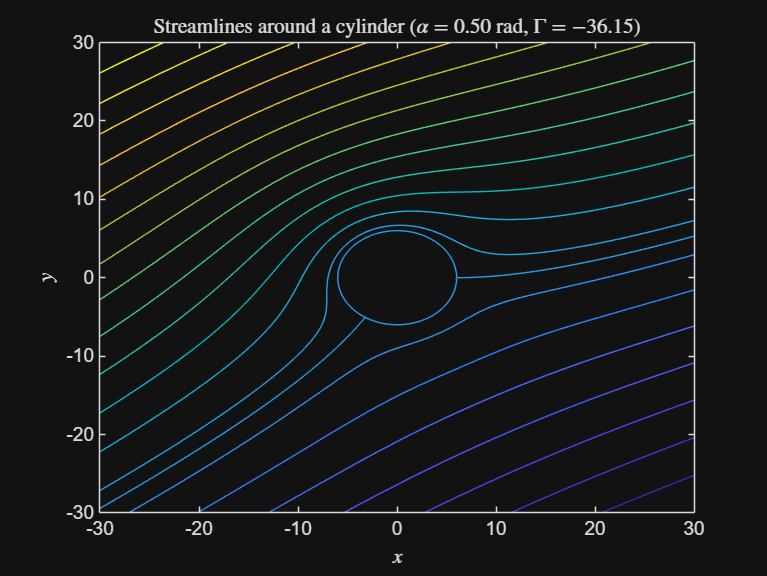

alpha = 0.5; % angle, from x axis, of flow in radions
a = 6; % circle radius
b = 6*0.8; % elliptical "squish factor"
L = 30; % length of simulation axis
P = 300; % number of pointse in numerical simulation
kutta = -4*pi*a*sin(alpha); % Kutta condition for lift
Gamma = kutta; % set circulation to kutta condition or 0

x = linspace(-L,L,P); % generates x domain
y = linspace(-L,L,P); % generates y domain

[x,y] = meshgrid(x,y); % generates x y plane

z = x + 1i*y; % base imaginary number

Z = z + b^2./(z - 1); % airfoil transform

Z_Cam = z + b^2./(z - 1 + 1i); %cambered airfoil transform

% genrates circulated cylinder flow
f = z*exp(-1i*alpha);
milne = a^2*exp(1i*alpha)./z;
circulation = -(1i*Gamma/(2*pi))*log(z);

% final complex potential
w = f + milne + circulation;

%complex derivative
dwdz = exp(-1i*alpha)-U*a^2*exp(1i*alpha)./z.^2 - (1i*Gamma./(2*pi*z));
u = real(dwdz);
v = -imag(dwdz);

%streamfunction, balanced to 0 around the body
psi = imag(w) + log(a)*Gamma/(2*pi);
psi_f = psi;

%remove singularity inside the body
mask = abs(z) < a;

mask_f = abs(z) < a - 2*L/P;

psi(mask) = NaN;
u(mask) = NaN;
v(mask) = NaN;

psi_f(mask_f) = NaN;

% cylinder flow
contour(x,y,psi,20)
hold on
contour(x,y,psi_f,[0,0])
%streamslice(x, y, u, v, 0.5);
title(sprintf('Streamlines around a cylinder ($\\alpha = %.2f$ rad, $\\Gamma = %.2f$)', ...
              alpha, Gamma), 'Interpreter','latex')

xlabel('$x$', 'Interpreter','latex')
ylabel('$y$', 'Interpreter','latex')

xlim([-L L])
ylim([-L L])

hold off

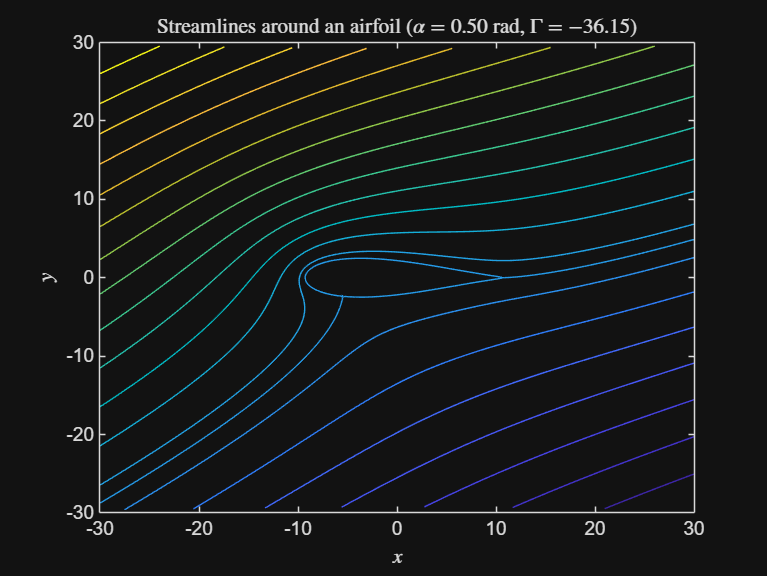



% airfoil flow
contour(real(Z),imag(Z),psi,20)
hold on
contour(real(Z),imag(Z),psi_f,[0,0])
title(sprintf('Streamlines around an airfoil  ($\\alpha = %.2f$ rad, $\\Gamma = %.2f$)', ...
              alpha, Gamma), 'Interpreter','latex')

xlabel('$x$', 'Interpreter','latex')
ylabel('$y$', 'Interpreter','latex')

xlim([-L L])
ylim([-L L])

hold off

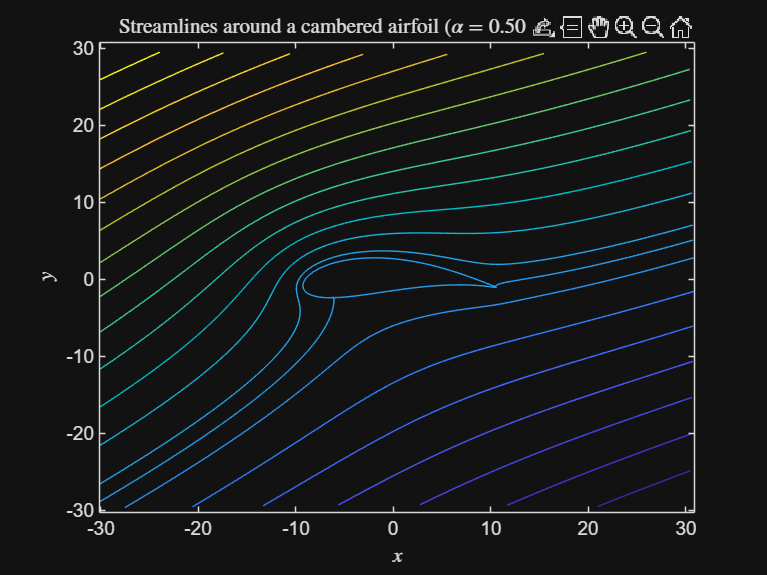


%cambered airfoil flow
contour(real(Z_Cam),imag(Z_Cam),psi,20)
hold on
contour(real(Z_Cam),imag(Z_Cam),psi_f,[0,0])
title(sprintf('Streamlines around a cambered airfoil  ($\\alpha = %.2f$ rad, $\\Gamma = %.2f$)', ...
              alpha, Gamma), 'Interpreter','latex')

xlabel('$x$', 'Interpreter','latex')
ylabel('$y$', 'Interpreter','latex')

xlim([-L L])
ylim([-L L])

hold off